# Electricity Revenue

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

electricity = readtable("../data/electricity.csv"); 

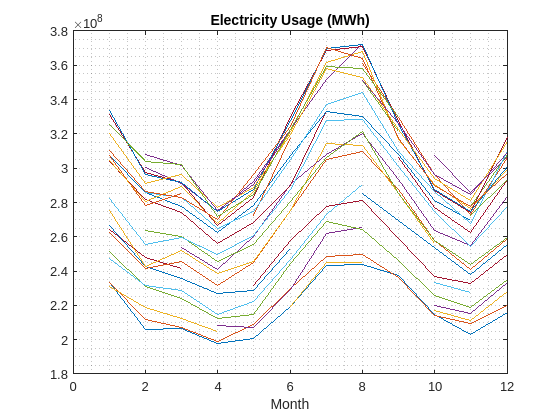

electricity = electricity(1:find(electricity.Date=='12/01/2015'), :);
com = reshape(electricity.Commercial, 12, []);
res = reshape(electricity.Residential, 12, []);
ind = reshape(electricity.Industrial, 12, []);

usage = com + res + ind;
price = price * 1000 / 100;

plot(usage)
grid minor
title("Electricity Usage (MWh)")
xlabel("Month")

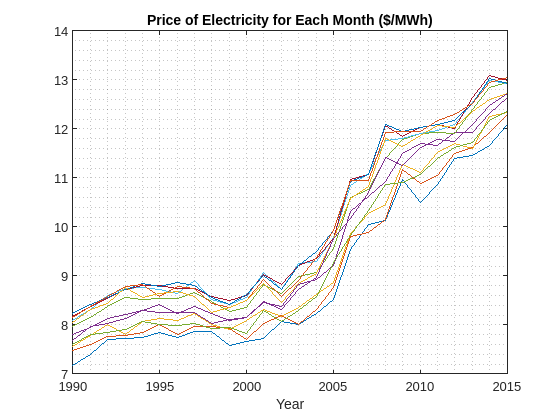


load ../data/electricity.mat
plot(1990:2015, price')
grid minor
title("Price of Electricity for Each Month ($/MWh)")
xlabel("Year")

## Task 1

revenue = price .* usage

revenue = 1.0e+12 *

    0.6841    0.6952    0.7041    0.7254    0.8034    0.7581    0.8421    0.8351    0.8073    0.8427    0.8392    0.9827    0.9429    0.9946    1.0473    1.0672    1.1496    1.2599    1.3524    1.4954    1.5475    1.5771    1.4360    1.5100    1.7075    1.6638
    0.5572    0.6042    0.6389    0.6502    0.7037    0.6942    0.7502    0.7202    0.6902    0.6868    0.7600    0.8030    0.7907    0.8897    0.9363    0.9341    1.0243    1.2016    1.2045    1.2885    1.3374    1.3284    1.2424    1.3153    1.5338    1.5209
    0.5443    0.5751    0.5905    0.6478    0.6456    0.6468    0.7034    0.6709    0.6885    0.7066    0.6854    0.7721    0.7785    0.8312    0.8525    0.9235    1.0358    1.0854    1.1198    1.2014    1.2414    1.2090    1.1621    1.3016    1.3996    1.4427
    0.5015    0.5256    0.5497    0.5665    0.5766    0.5769    0.6148    0.6095    0.6103    0.6250    0.6219    0.6974    0.7151    0.7357    0.7628    0.8002    0.9220    0.9595    1.0075    1.

## Task 2

revBillion = round(revenue / 1e9, 3);

This code plots the prices for each year by month.

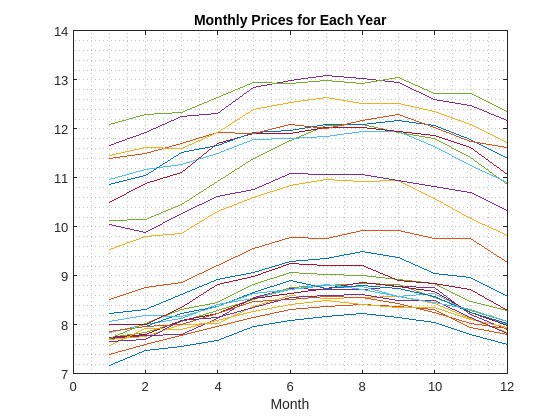

plot(price)
grid minor
title("Monthly Prices for Each Year")
xlabel("Month")

## Task 3

priceInfl = price(:, end) ./ price(:, 1)

priceInfl =     1.6873
    1.6429
    1.6308
    1.6429
    1.6269
    1.5967
    1.5881
    1.5698
    1.6013
    1.5827


## Further Practice